sqrt函数开平方根，sqrt(x) > 0 所以g只有正数部分

real函数返回复数的实数部

圆的标准函数 （x-1)^2 + (y+2)^2 + z^2 = 9/2

[x,y] = meshgrid(-5:.2:5);
g = sqrt(x.*2 -x.^2-y.^2 - y.*4 - 0.5) 

g =    0.0000 + 6.3640i   0.0000 + 6.1758i   0.0000 + 5.9883i   0.0000 + 5.8017i   0.0000 + 5.6160i   0.0000 + 5.4314i   0.0000 + 5.2479i   0.0000 + 5.0656i   0.0000 + 4.8847i   0.0000 + 4.7053i   0.0000 + 4.5277i   0.0000 + 4.3520i   0.0000 + 4.1785i   0.0000 + 4.0075i   0.0000 + 3.8393i   0.0000 + 3.6742i   0.0000 + 3.5128i   0.0000 + 3.3556i   0.0000 + 3.2031i   0.0000 + 3.0561i   0.0000 + 2.9155i   0.0000 + 2.7821i   0.0000 + 2.6571i   0.0000 + 2.5417i   0.0000 + 2.4372i   0.0000 + 2.3452i   0.0000 + 2.2672i   0.0000 + 2.2045i   0.0000 + 2.1587i   0.0000 + 2.1307i   0.0000 + 2.1213i   0.0000 + 2.1307i   0.0000 + 2.1587i   0.0000 + 2.2045i   0.0000 + 2.2672i   0.0000 + 2.3452i   0.0000 + 2.4372i   0.0000 + 2.5417i   0.0000 + 2.6571i   0.0000 + 2.7821i   0.0000 + 2.9155i   0.0000 + 3.0561i   0.0000 + 3.2031i   0.0000 + 3.3556i   0.0000 + 3.5128i   0.0000 + 3.6742i   0.0000 + 3.8393i   0.0000 + 4.0075i   0.0000 + 4.1785i   0.0000 + 4.3520i
   0.0000 + 6.2722i   0.0000 + 6.0811i   0.00

surf(x, y, real(g))
hold on
surf(x, y, -real(g))
hold on


现在把圆心上调 （x-1)^2 + (y+2)^2 + (z-8)^2 = 9/2


%z = sqrt(x.*2 -x.^2-y.^2 - y.*4 -65.5 + z.*16) 
%surf(x, y, real(z))
%hold on 

z = sqrt(-60 - x.^2 - y.^2 + z*16)

z =    8.8891 + 5.6646i   8.9627 + 5.5207i   9.0366 + 5.3834i   9.1102 + 5.2526i   9.1832 + 5.1284i   9.2551 + 5.0109i   9.3257 + 4.9000i   9.3944 + 4.7957i   9.4612 + 4.6979i   9.5255 + 4.6066i   9.5871 + 4.5215i   9.6459 + 4.4427i   9.7014 + 4.3699i   9.7536 + 4.3032i   9.8023 + 4.2423i   9.8472 + 4.1871i   9.8882 + 4.1376i   9.9252 + 4.0936i   9.9582 + 4.0550i   9.9869 + 4.0217i  10.0113 + 3.9937i  10.0313 + 3.9709i  10.0470 + 3.9532i  10.0582 + 3.9406i  10.0650 + 3.9331i  10.0672 + 3.9305i  10.0650 + 3.9331i  10.0582 + 3.9406i  10.0470 + 3.9532i  10.0313 + 3.9709i  10.0113 + 3.9937i   9.9869 + 4.0217i   9.9582 + 4.0550i   9.9252 + 4.0936i   9.8882 + 4.1376i   9.8472 + 4.1871i   9.8023 + 4.2423i   9.7536 + 4.3032i   9.7014 + 4.3699i   9.6459 + 4.4427i   9.5871 + 4.5215i   9.5255 + 4.6066i   9.4612 + 4.6979i   9.3944 + 4.7957i   9.3257 + 4.9000i   9.2551 + 5.0109i   9.1832 + 5.1284i   9.1102 + 5.2526i   9.0366 + 5.3834i   8.9627 + 5.5207i
   8.9627 + 5.5207i   9.0398 + 5.3775i   9.11

surf(x, y, real(z))
hold on
surf(x, y, -real(z))
hold on


圆

h=4; % 高度
t=0:0.1:(2*pi);
t=[t,0];
plot3(sin(t),cos(t), h*ones(size(t)))

hold on 


使用sphere函数生成圆的坐标矩阵


[x1, y1, z1]=sphere(50);
mesh(2*x1,2*y1,2*z1+15);
hold on


圆方程 x^2+y^2+z^2=1


z2 = 1 - x.^2 - y.^2

z2 =   -49.0000  -47.0400  -45.1600  -43.3600  -41.6400  -40.0000  -38.4400  -36.9600  -35.5600  -34.2400  -33.0000  -31.8400  -30.7600  -29.7600  -28.8400  -28.0000  -27.2400  -26.5600  -25.9600  -25.4400  -25.0000  -24.6400  -24.3600  -24.1600  -24.0400  -24.0000  -24.0400  -24.1600  -24.3600  -24.6400  -25.0000  -25.4400  -25.9600  -26.5600  -27.2400  -28.0000  -28.8400  -29.7600  -30.7600  -31.8400  -33.0000  -34.2400  -35.5600  -36.9600  -38.4400  -40.0000  -41.6400  -43.3600  -45.1600  -47.0400
  -47.0400  -45.0800  -43.2000  -41.4000  -39.6800  -38.0400  -36.4800  -35.0000  -33.6000  -32.2800  -31.0400  -29.8800  -28.8000  -27.8000  -26.8800  -26.0400  -25.2800  -24.6000  -24.0000  -23.4800  -23.0400  -22.6800  -22.4000  -22.2000  -22.0800  -22.0400  -22.0800  -22.2000  -22.4000  -22.6800  -23.0400  -23.4800  -24.0000  -24.6000  -25.2800  -26.0400  -26.8800  -27.8000  -28.8000  -29.8800  -31.0400  -32.2800  -33.6000  -35.0000  -36.4800  -38.0400  -39.6800  -41.4000  -43.2000  -4

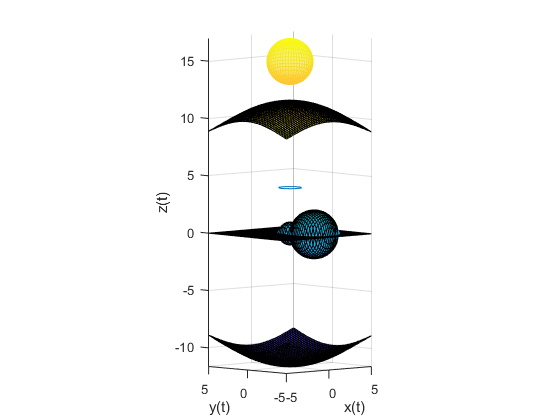

surf(x, y, real(sqrt(z2)))
hold on 
surf(x, y, -real(sqrt(z2)))
hold on 
xlabel('x(t)')
ylabel('y(t)')
zlabel('z(t)')
axis equal 